# **Implementación EC en matlab de modulación digital y analógica**

Andrés Fernando Jerez Medina - 2190416

Jorge Eduardo Angarita Perez - 2190427

Sergio Sebastián Oliveros Sepulveda - 2190396 

## **Punto 2:**

Parámetros:

fm = 100;
fc = fm*10;
fs = fc*5;
Ts = 1/fs;
nper = 3;
Tend = 1/fm*nper;
Ac = 1;
Df = 100;

Modulación en tiempo

t = 0:Ts:(Tend-Ts);
n = length(t);
m_t = 10*sin(2*pi*fm*t);
x_t = Ac*cos(Df*cumsum(m_t)*Ts);
y_t = Ac*sin(Df*cumsum(m_t)*Ts);
g_t = x_t + 1j*y_t;
s_t = x_t.*cos(2*pi*fc*t)-y_t.*sin(2*pi*fc*t);

En frecuencia:

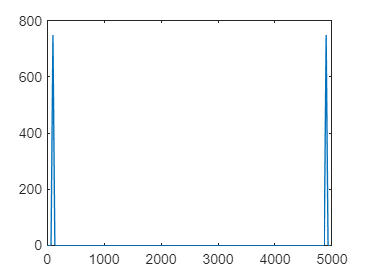

f = (0:n-1)*(fs/n);
m_f = fft(m_t);
g_f = fft(g_t);
s_f = fft(s_t);
plot(f,abs(m_f))